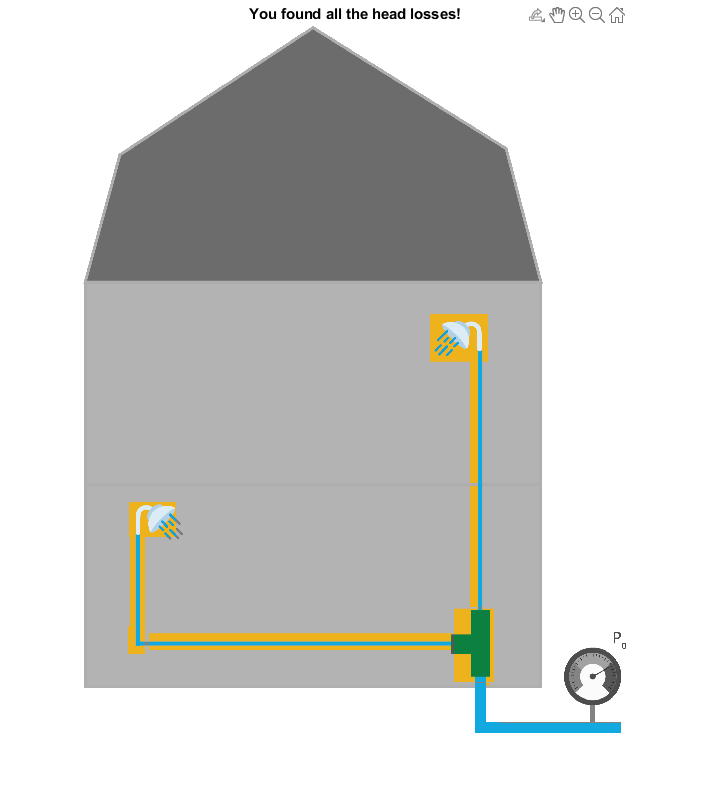

clear
load ROI.mat
[I,~,A] = imread(gTruth.DataSource.Source{1}); 
Im(:,:,1) = rgb2gray(I);
Im(:,:,2) = rgb2gray(I);
Im(:,:,3) = rgb2gray(I);

img = imshow(Im);
HeadLoss = gTruth.LabelData.HeadLoss{1};
found = zeros(size(HeadLoss,1),1);
tobefound = size(found, 1);
while ~all(found)
    title("There is "+num2str(tobefound-sum(found))+" remaining!")
    [xi,yi] = ginput(1);
    idx = HeadLoss(:,1) <= xi & xi <= HeadLoss(:,1)+HeadLoss(:,3) ...
        & HeadLoss(:,2) <= yi & yi <= HeadLoss(:,2)+HeadLoss(:,4);
    idx = find(idx);
    found(idx) = 1;
    if ~isempty(idx)
        for j = 1:size(idx)
            rc = HeadLoss(idx(j),:);
            xl = [rc(2):rc(2)+rc(4)]; xl(xl > size(I,1)) = []; xl(xl < 1) = []; xl = floor(xl);
            yl = [rc(1):rc(1)+rc(3)]; yl(yl > size(I,2)) = []; yl(yl < 1) = []; yl = floor(yl);
            img.CData(xl,yl,:) = I(xl,yl,:);
        end
    else
    end
end
title("You found all the head losses!")